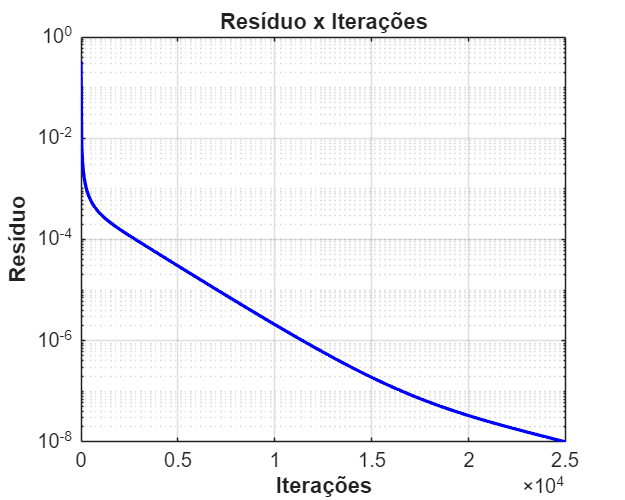

% =========================================================================
% PLOT DOS RESULTADOS DE VALIDAÇÃO - EQUAÇÃO DE POISSON
% =========================================================================
clear; clc; close all;

%% 1. GRÁFICO 1: O DECAIMENTO DO RESÍDUO
% Carrega o arquivo do resíduo (segundo passo de tempo)
dados_res = load('norma_iter_poisson.dat');
iteracoes = dados_res(:, 1);
residuo   = dados_res(:, 2);

figure('Name', 'Resíduo de Poisson', 'Color', 'w', 'Position', [750, 200, 500, 400]);
semilogy(iteracoes, residuo, 'b-', 'LineWidth', 2);
grid on;

ax = gca; 
set(ax, 'YMinorGrid', 'on', 'FontSize', 12);
ax.XAxis.Exponent = 4;
xlabel('Iterações', 'FontWeight', 'bold');
ylabel('Resíduo', 'FontWeight', 'bold');
title('Resíduo x Iterações', 'FontWeight', 'bold');
xlim([0 max(iteracoes)]);

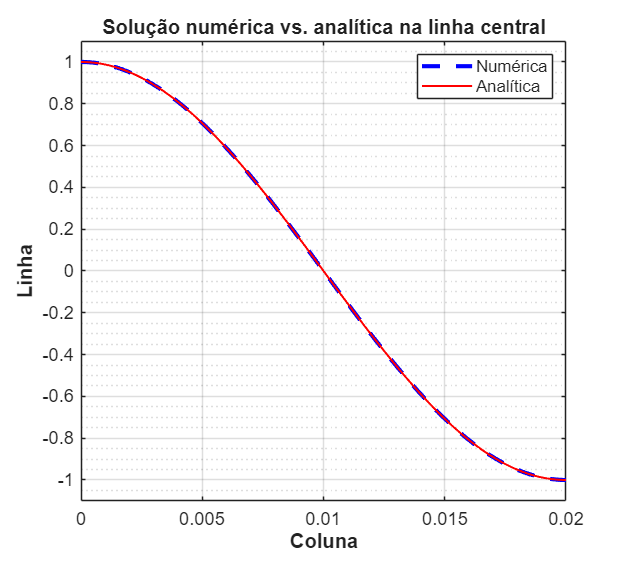

% =========================================================================
% PLOT DA LINHA CENTRAL: NUMÉRICA VS ANALÍTICA (Equação de Poisson)
% =========================================================================

% Parâmetros da malha (devem bater com o parametros_poisson.txt)
Nx = 213; 
Ny = 213;
Lx = 0.02; Ly = 0.02;

% 1. Carrega os dados numéricos gerados pelo Fortran
% (Ajuste o caminho da pasta se necessário)
dados = load('mapa_calor_poisson.dat'); 
X_vetor = dados(:, 1);
Y_vetor = dados(:, 2);
T_vetor = dados(:, 3);

% Transforma as colunas em matrizes 2D
X = reshape(X_vetor, [Nx, Ny])';
Y = reshape(Y_vetor, [Nx, Ny])';
T = reshape(T_vetor, [Nx, Ny])';

% 2. Isola a Linha Central Vertical do chip (x = 0.5)
idx_centro = round(Nx / 2);
y_linha = Y(:, idx_centro);     % Eixo Y (A "Coluna" do gráfico)
T_num   = T(:, idx_centro);     % Temperatura Numérica (A "Linha" do gráfico)
x_linha = X(:, idx_centro);     % Vetor de posição x constante (x = 0.5)

% 3. Calcula a Solução Analítica Exata para esta mesma linha
T_analitico = sin((pi * x_linha) / Lx) .* cos((pi * y_linha) / Ly);

% 4. Plota o Gráfico Comparativo
figure('Name', 'Validação Analítica', 'Color', 'w', 'Position', [200, 200, 500, 450]);

% Linha Numérica (Azul tracejada, mais grossa para destacar atrás)
plot(y_linha, T_num, 'b--', 'LineWidth', 2.5); 
hold on;

% Linha Analítica (Vermelha contínua, ligeiramente mais fina por cima)
plot(y_linha, T_analitico, 'r-', 'LineWidth', 1.2); 

% Formatação visual igual à do relatório da UTFPR
grid on;
set(gca, 'YMinorGrid', 'on', 'FontSize', 11);

% Rótulos literais conforme o PDF
xlabel('Coluna', 'FontWeight', 'bold');
ylabel('Linha', 'FontWeight', 'bold');
title('Solução numérica vs. analítica na linha central', 'FontWeight', 'bold', 'FontSize', 12);

% Legenda no canto superior direito
legend({'Numérica', 'Analítica'}, 'Location', 'northeast', 'FontSize', 10);

% Ajuste exato dos limites do gráfico
xlim([0 Ly]);
ylim([-1.1 1.1]); % Ajustado para abraçar a nova curva trigonométrica

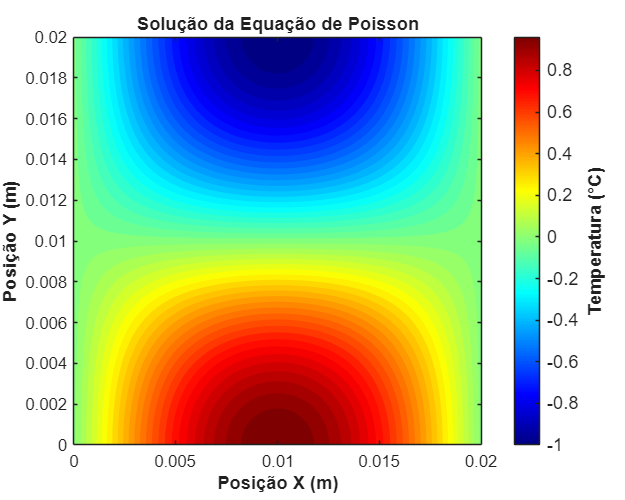

%% 2. GRÁFICO 3: O MAPA DE CALOR )
% Parâmetros da malha
Nx = 213; 
Ny = 213;

% Carrega o mapa de calor
dados_mapa = load('mapa_calor_poisson.dat');
X_vetor = dados_mapa(:, 1);
Y_vetor = dados_mapa(:, 2);
T_vetor = dados_mapa(:, 3);

% Transforma as colunas em matrizes 2D para o plot
X = reshape(X_vetor, [Nx, Ny])';
Y = reshape(Y_vetor, [Nx, Ny])';
T = reshape(T_vetor, [Nx, Ny])';

figure('Name', 'Mapa de Calor - Poisson', 'Color', 'w', 'Position', [650, 100, 500, 400]);
contourf(X, Y, T, 50, 'LineColor', 'none'); % 50 níveis de cores sem linhas pretas
colormap('jet');
c = colorbar;
c.Label.String = 'Temperatura (°C)';
c.Label.FontWeight = 'bold';
c.FontSize = 11;

xlabel('Posição X (m)', 'FontWeight', 'bold');
ylabel('Posição Y (m)', 'FontWeight', 'bold');
title('Solução da Equação de Poisson', 'FontWeight', 'bold');
axis equal;
axis tight;